theta_z = 2.98

theta_z = 2.9800

theta_xy = combinations(0:0.01:pi, 0:0.01:pi);
theta = [theta_xy.Var1, theta_xy.Var2, ones(size(theta_xy.Var1)) * theta_z];

theta_max = deg2rad(45);
c = zeros(size(theta_xy.Var1));
for i = 1 : size(theta, 1)
    c(i) = pitch_constraint(theta(i,:), 0);
end

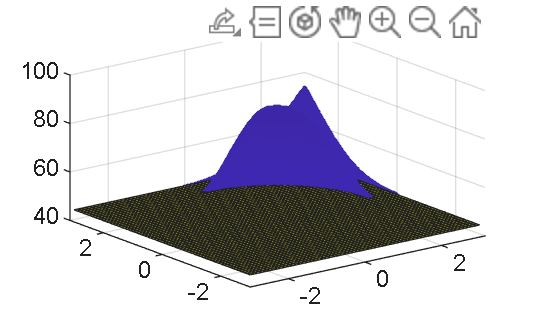

figure
scatter3(theta(:, 1), theta(:, 2), acosd(c), 1, c); hold on
[x y] = meshgrid(-3:0.1:3); % Generate x and y data
z = ones(size(x, 1))*rad2deg(theta_max); % Generate z data
surf(x, y, z) % Plot the surface
hold off

## Helper Functions

function [c] = angle_from_vec_constraint(n, b, tau, theta_max)
   theta = norm(tau);
   lambda = tau / theta;
   
   c = cos(theta_max) - (dot(n, b) * cos(theta) - dot(n, cross(b, lambda)) * sin(theta) + dot(b, lambda) * dot(n, lambda) * (1 - cos(theta)));
end

function [c] = pitch_constraint(tau, theta_max)
   theta = norm(tau);
   lambda = tau / theta;
   
   c = cos(theta_max) - (cos(theta) + lambda(3) ^ 2 * (1 - cos(theta)));
end